Esercizio 2 - FFT su segnale 2D, solo analisi

Lettura immagine

x = imread('vesuvio_cratere.jpg');
x = double(rgb2gray(x)) ./ 255;

Trasformata immagine

[M, N] = size(x);
X = fft2(x, M, N);
Xf = fftshift(X);
m = -0.5:(1/M):(0.5-1/M);
n = -0.5:(1/N):(0.5-1/N);

Visualizzazione di spettri di ampiezza e di fase rispetto all'immagine

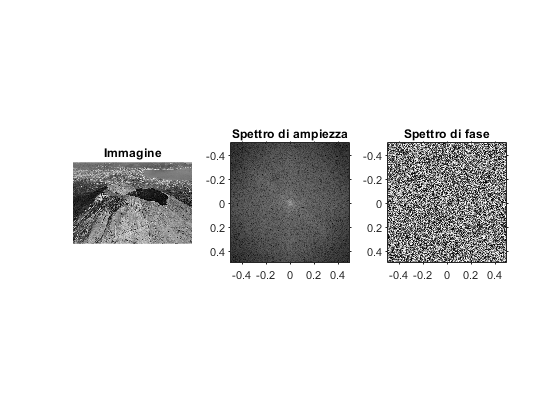

figure();
subplot(1,3,1); imshow(x); title('Immagine');
subplot(1,3,2); imshow(log(abs(Xf)+1), [], 'XData', n, 'YData', m);
axis on; title('Spettro di ampiezza');
subplot(1,3,3); imshow(angle(Xf), [], 'XData', n, 'YData', m);
axis on; title('Spettro di fase');

Ricostruzione immagine solo con ampiezza e solo con fase e confronto con l'originale

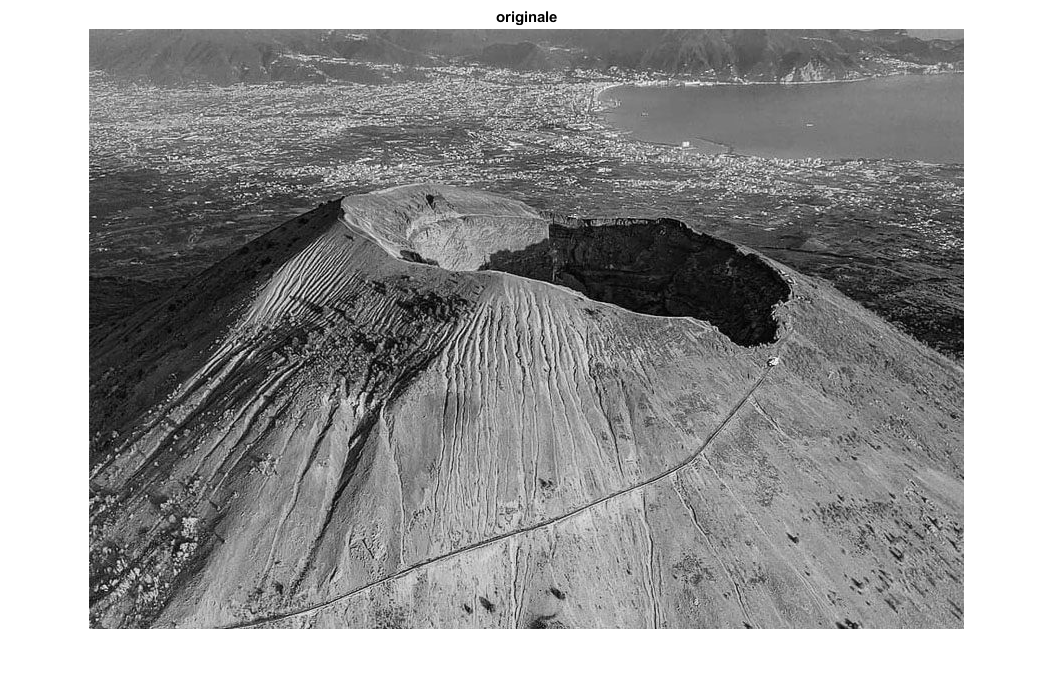

X1 = abs(X);
x1 = ifft2(X1);
X2 = X ./ abs(X); % oppure exp(1j .* angle(X));
x2 = ifft2(X2);
figure(); imshow(x); title('originale');

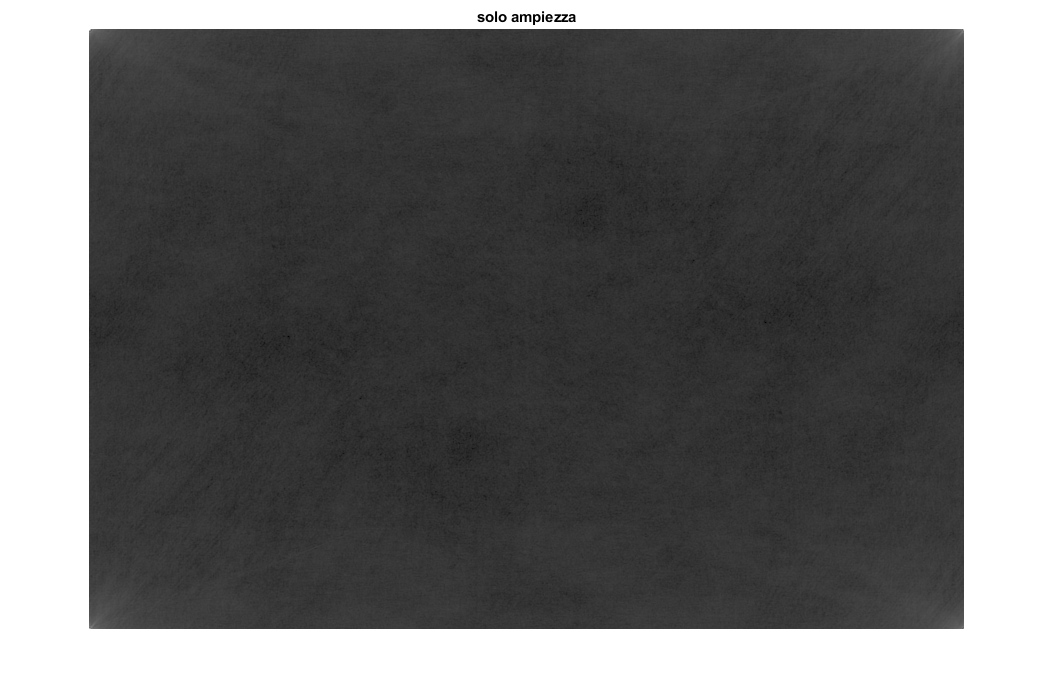

figure(); imshow((x1-min(x1(:))).^0.3, []); title('solo ampiezza');

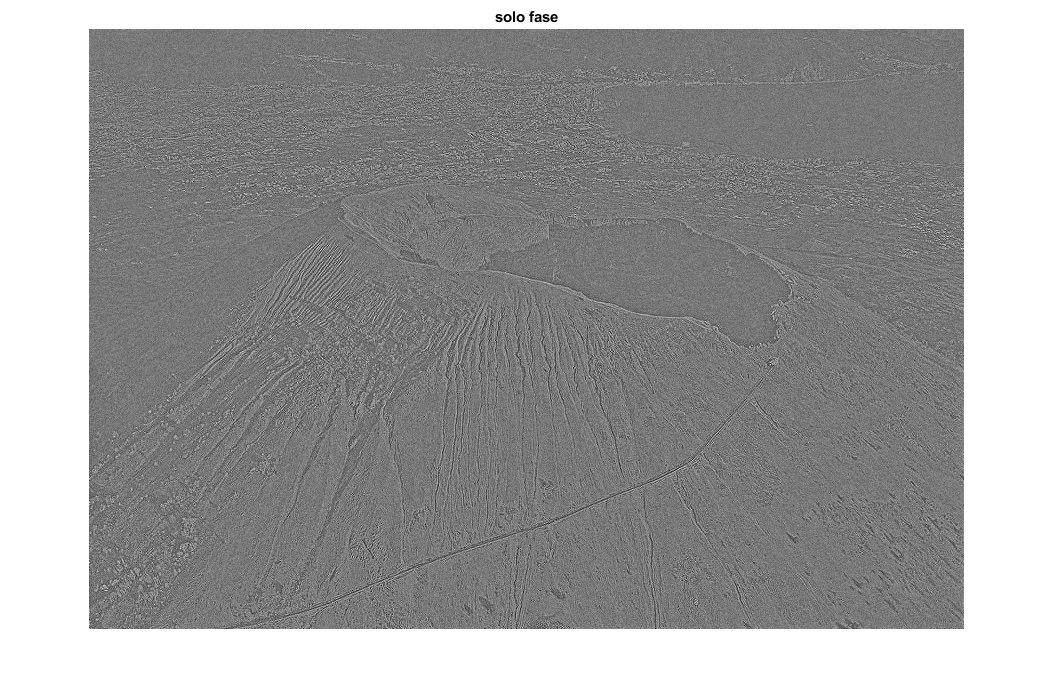

figure(); imshow(x2, []); title('solo fase');